# **Simulações de antenas *****microstrip***** com células SRR para 5G**

`por Renan Machado`

Este é um *live script* em MatLAB que visa construir um *dataset* de simulações de antenas com metamateriais para treinar modelos preditivos de *machine learning*. Os parâmetros dos metamateriais, como largura e comprimento da célula, disposição do arranjo, e outros, serão variados em uma faixa de valores adequados, procurando respeitar as referências oferecidas pela literatura. O *software* utilizado para as simulações eletromagnéticas é o **CST Studio Lite©**, utilizando o módulo **Microwave Studio**. Para o controle automatizado do software, será utilizada a API desenvolvida por Symeon Symeonidis, Stefanos Tsantilas e Stelios Mitilineos, tendo o código fonte e a documentação disponíveis [aqui](https://github.com/simos421/CST-MATLAB-API). A API original foi modificada e está disponível no repositório.

## Inicialização do CST

Para correta utilização da API, antes é necessário adicionar seu código fonte ao *path*, dessa forma:

addpath(genpath('CST-MATLAB-API-master'));

Para iniciar a aplicação do CST, utilizamos o seguinte comando:

cst = actxserver('CSTStudio.application');

Agora, com o CST aberto, podemos inicializar o Microwave Studio.

mws = cst.invoke('NewMWS');

Você deve ter na sua tela algo parecido como a figura abaixo.

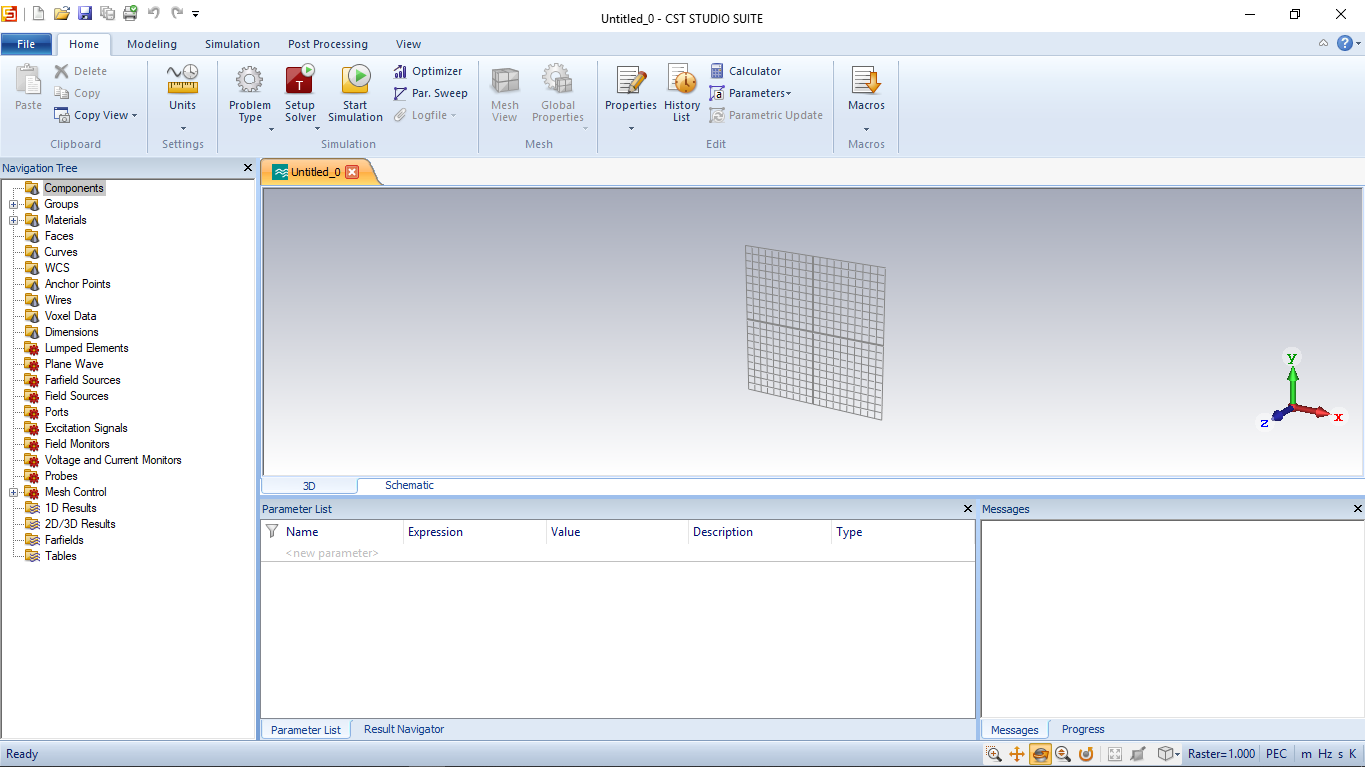

## Configurando o ambiente de simulação

Na MCW (*Mobile World Congress*) de 2019, o presidente da ANATEL, Leonardo de Morais, anunciou o leilão de 200 MHz na frequência de 3,5 GHz que serão destinados para implantação do 5G no Brasil. Aqui, a frequência será esse domínio reservado na frequência de 3.5GHz que a ANATEL anunciou. 

Inicialmente, precisamos definir as unidades padrão. É importante ressaltar que a **unidade de comprimento é micrometros** (1e-6 metros). Com isso, também é necessário definir o intervalo de frequência que será simulado, aqui serão simulados 3% da frequência central como limites inferior e superior. Assim, é possível inicializar a *mesh* e definir as condições de contorno.

fcenter = 3.5;
fmin = fcenter * 0.97
fmax = fcenter * 1.03

Em código:

CstDefineUnits(mws, 'um', 'GHz', 's', 'Kelvin', 'V', 'A', 'Ohm', 'S', 'PikoF', 'NanoH');
CstDefineFrequencyRange(mws, fmin, fmax);
CstMeshInitiator(mws); 

A antena estará no espaço livre, então:

%Condições de contorno
Xmin = 'expanded open';
Xmax = 'expanded open';
Ymin = 'expanded open';
Ymax = 'expanded open';
Zmin = 'expanded open';
Zmax = 'expanded open';

CstDefineOpenBoundary(mws, fmin, Xmin, Xmax, Ymin, Ymax, Zmin, Zmax);

Em seguida, precisamos definir o material do fundo:

XminSpace = 0;
XmaxSpace = 0;
YminSpace = 0;
YmaxSpace = 0;
ZminSpace = 0;
ZmaxSpace = 0;

CstDefineBackroundMaterial(mws, XminSpace, XmaxSpace, YminSpace, YmaxSpace, ZminSpace, ZmaxSpace);

## Definição de materiais

Para a definição de materiais que serão utilizados nos componentes, é preciso definir as propriedades do material de acordo com a biblioteca do CST e fazer uma função em MatLAB com todas essas propriedades, juntamente com o nome do material. Somente depois disso é que podemos utilizar o nome do material no código. Na API, já temos funções para definir materiais como cobre e FR4 com perdas.

metal = CstCopperAnnealedLossy(mws)
[dieletric, epsilon_r] = CstFR4lossy(mws)

Além disso, precisamos definir a altura da folha de metal (nesse caso, cobre).

t = 0.035*1e3; % in um (t from thickness)

## *Design* da antena base

Na criação do *dataset*, os metamateriais serão aplicados em uma antena base que possui bons parâmetros. Essa antena será projetada com base em toda a referência bibliográfica existente. No *design *de antenas, é necessário definir primariamente o material do substrato e a frequência de aplicação. A altura do substrato também precisa ser predefinida com antecedência. A bibliografia sugere uma escolha entre $0,03\lambda$ e $0,5\lambda$, tendo uma preferência por substratos mais finos por resultarem em uma melhor eficiência de radiação. Para esse projeto:

h = 1700;

As variáveis associadas a geometria de uma antena *microstrip* são essas mostradas na figura abaixo. 

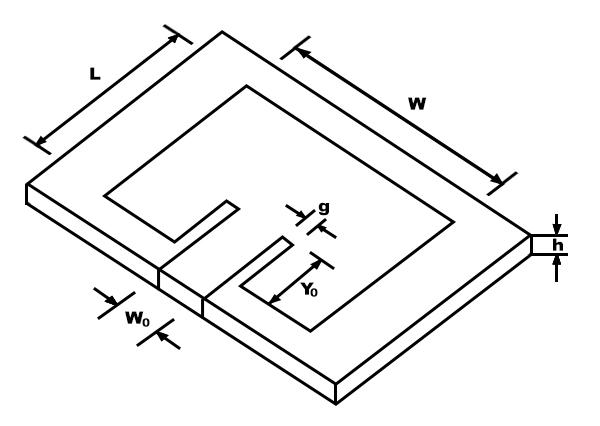

Para uma obtermos uma boa eficiência de radiação, (BALANIS, 2005) nos dá que:


$$W=\frac{c}{2f_r }\sqrt{\;\frac{2}{{\epsilon \;}_r +1}}$$


W = 0.9*3e8/(2*fcenter*1e9)*sqrt(2/(epsilon_r+1))*1e6 % in um

Antes de definirmos $L$, precisamos calcular a constante dielétrica efetiva da antena, já que algumas ondas viajam no substrato e algumas no ar. Segundo (BALANIS, 2005):


$$\epsilon_{\mathrm{reff}} =\frac{\epsilon_r +1}{2}+\frac{\epsilon_r -1}{2}{\left(1+12\;\frac{h}{W}\right)}^{-\frac{1}{2}}$$


epsilon_reff = (epsilon_r+1)/2+((epsilon_r-1)/2).*(1+(12/W).*h).^(-1/2)

Agora que temos a constante dielétrica efetiva, calculamos o quão maior o patch aparenta ser do que realmente é através de:


$$\Delta L=0,412h\;\frac{\left(\epsilon_{\mathrm{reff}} +0,3\right)\left(\frac{W}{h}+0,264\right)}{\left(\epsilon_{\mathrm{reff}} -0,258\right)\left(\frac{W}{h}+0,8\right)}$$


delta_l = 0.412.*h.*((epsilon_reff+0.3).*(W./h+0.264))./((epsilon_reff-0.258).*(W./h+0.8))

Finalmente, temos que:


$$L=\frac{c}{2f_r \sqrt{\epsilon_{\mathrm{reff}} }}-2\Delta L$$


l = 0.98.*3e5./(2*fcenter*sqrt(epsilon_reff))-2.*delta_l

Por último, os parâmetros restantes normalmente são:


$$Y_0 =4h$$



$$g\approx 1000\;\mathrm{um}$$



$$W_0 =3,5g$$


Y0 = 4*h
g = 1000;
W0 = 3.5*g

## Intervalo de valores para a antena

Alguns intervalos estão em função do comprimento de onda $\lambda$, de forma que:


$$\lambda =\frac{c}{f}$$


f_step = 100e-3;
f = fmin:f_step:fmax % in GHz (1e9 Hz)
lambda = 3e5./f % in um (1e-6 m)

De acordo com a literatura, temos que:


$$0,003\lambda \;\le h\le 0,05\lambda$$


hmin = 0.003;
hmax = 0.05;
h_step = (hmax - hmin)/(4 - 1);

[h_factor, h] = GetAntennaValues(hmin, hmax, h_step, lambda)

Antes de definirmos $L$, precisamos calcular a constante dielétrica efetiva da antena, já que algumas ondas viajam no substrato e algumas no ar. Segundo (BALANIS, 2005):


$$\epsilon_{\mathrm{reff}} =\frac{\epsilon_r +1}{2}+\frac{\epsilon_r -1}{2}{\left(1+12\;\frac{h}{W}\right)}^{-\frac{1}{2}}$$


epsilon_reff = (epsilon_r+1)/2+((epsilon_r-1)/2).*(1+(12/W).*h).^(-1/2)

Agora que temos a constante dielétrica efetiva, calculamos o quão maior o patch aparenta ser do que realmente é através de:


$$\Delta L=0,412h\;\frac{\left(\epsilon_{\mathrm{reff}} +0,3\right)\left(\frac{W}{h}+0,264\right)}{\left(\epsilon_{\mathrm{reff}} -0,258\right)\left(\frac{W}{h}+0,8\right)}$$


delta_l = 0.412.*h.*((epsilon_reff+0.3).*(W./h+0.264))./((epsilon_reff-0.258).*(W./h+0.8))

Finalmente, temos que:


$$L=\frac{c}{2f_r \sqrt{\epsilon_{\mathrm{reff}} }}-2\Delta L$$


l = 3e5./(2*fcenter*sqrt(epsilon_reff))-2.*delta_l

Por último, os parâmetros restantes normalmente estão nessa faixa de valores:


$$h\le Y_0 \le 3h$$



$$2h\le W_0 \le 2\ldotp 2h$$



$$0,2W_0 \le g\le 0,3W_0$$


y0min = 1;
y0max = 3;
[h_rows, h_cols] = size(h);
y0_step = (y0max - y0min)/(h_rows-1);

[y0_factor, y0] = GetAntennaValues(y0min, y0max, y0_step, h)
w0min = 2;
w0max = 2.2;
w0_step = (w0max - w0min)/(3 - 1);

[w0_factor, w0] = GetAntennaValues(w0min, w0max, w0_step, h)
gmin = 0.2;
gmax = 0.3;
g_step = (gmax - gmin)/(length(w0_factor)-1);

[g_factor, g] = GetAntennaValues(gmin, gmax, g_step, w0)

Vamos transformar todos os parâmetros que estão em forma de matriz em um array linear através da função *Flat. *Essa função também remove os valores duplicados e ordena do menor para o maior.

H = Flat(h(1,:))
L = Flat(l(1,:))
Y0 = Flat(y0(:,1))
W0 = Flat(w0)
G = Flat(g)

## Intervalo de valores para as células SRR

% TODO

## Simulação

O número de simulações rodadas é:

n_sim = length(H)*length(L)*length(Y0)*length(W0)*length(G)

Variando os parâmetros:

count = 1;
for h = 1:length(H)
    for l = 1:length(L)
        for y0 = 1:length(Y0)
            for w0 = 1:length(W0)
                for g = 1:length(G)
                    DrawMicrostripAntenna(mws, W, L(l), t, H(h), Y0(y0), W0(w0), G(g), metal, dieletric);
                    DrawPort(mws, W, L(l), t, H(h), W0(w0));
                    
                    CstDefineFarfieldMonitor(mws,strcat('farfield (f=',num2str(fcenter),')'), fcenter);
                    
                    %Create template for Gain vs Frequency (name it Gain)
                    
                    CstDefineTimedomainSolver(mws,-40);
                    
                    ExportResults(mws, 'C:\Users\Renan\results', count, W, L(l), t, H(h), Y0(y0), W0(w0), G(g));
                    
                    CstDeleteComponent(mws, 'component1');
                    
                    %Emulate enter key press
                    
                    count = count + 1;
                end
            end
        end
    end
end